Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Delta hedging (Section 5.4)

Volker Ziemann, 211115, CC-BY-SA-4.0

With this example we provide the opportunity to explore delta hedging and, in particular, recreate the plots shown in Figure 5.3 in the book.  The simulation is based on following the value of a call option over 252 trading days as the stock value evolves with annual return $\rho$ and volatility $\sigma$. Note that we only take $\sigma$ into account when calculating the value of the option, but not when evolving the stock $S$ in order  to make the development more transparent.

The four sliders can be used to adjust the parameters of the simulation. In particular the return $\rho$, volatility $\sigma$, the risk-free rate $r_f$, and the strike price $K$.

rho=0.09;   % annual return 
sig=0.3;    % annual volatility
rf=0.05;    % risk free rate
K=1;      % strike price 

In the next section we define the duration of the simulation `T0` and the number of trading days `N`, as well as the initial stock price `S0`. then we allocate a number of arrays to store the stock price at each trading day, the value of the hedge, the amount of money to borrow from the bank, and the value of the money, originally received when selling the call option. We also prepare an array KK to display the constant value of the agreed-upon strike price

T0=1;      % one year
N=252;     % trading days
S0=1;      % initial share value
S=zeros(N,1); hedge=zeros(N,1); borrow=zeros(N,1); value=zeros(N,1); 
KK=K*ones(N,1);

At the start of the year, we calculate the value of the call option c0, the fraction of stocks $\Delta$= delta needed for the `hedge`, which we `borrow` from the bank. 

[c0,delta0]=black_scholes_call(S0,K,T0,rf,sig); 
S(1)=S0;
hedge(1)=delta0*S0;   % initial hedge
borrow(1)=hedge(1);   % borrow money for hedge
value(1)=c0;          % pocket the money for the sold option

Now we iterate through the 252 trading days and at the end of every daym we calculate the remaining time dt until maturity, the interest we have to pay for the borrowed money, the value of the money we received when selling the option, as well as the new stock value (with random variation turned off!). 

for i=2:N
    dt=T0*(N-i)/N;                 % trading days left until maturity
    interest=borrow(i-1)*rf/N;     % interest on borrowed
    value(i)=value(i-1)*exp(rf/N); % the money for the sold call option
    S(i)=S(i-1)*exp(rho/N);%*(1+sig*randn/sqrt(N));  % stocks growth rate

Given the updated stock value `S(i)`, we calculate the new hedging fraction `delta`, calculate the new value of the` hedge`, and figure out how much money we have to borrow, which is the difference in the values of the hedge and the inetest we need to pay for the borrowed money.

    [c,delta]=black_scholes_call(S(i),K,dt,rf,sig);  % calculate delta
    hedge(i)=delta*S(i);                             % optimal hedge
    borrow(i)=borrow(i-1)+hedge(i)-hedge(i-1)+interest;  % borrow to adjust hedge
end

Once we reach maturity after `N` trading days, we work out how much the hedging actually costs. If the option is *in the money*, our costs is the boorowed money, which includes the handed-over stock, to the holder of the option, minus the agreed-upon strike price K that I receive from the option holder.  If the option is out of the money. the hedge at the end is zero, but I had incurred interest payments along the way. Note that the `cost `calculated here is has to be compared to the `value` of the money received for the option `c0` that has increased in value at the risk-free rate.

if S(i) > K              % in the money
    cost=borrow(i)-K;    % need to repay the borrowed and receive strike price
else                     % out of the money
    cost=borrow(i);         
end

Finally we plot the stock value `S` as a solid black line, the strike price K as a dotted black line, the hedge in red and the borrowed money as a blue dashed line. 

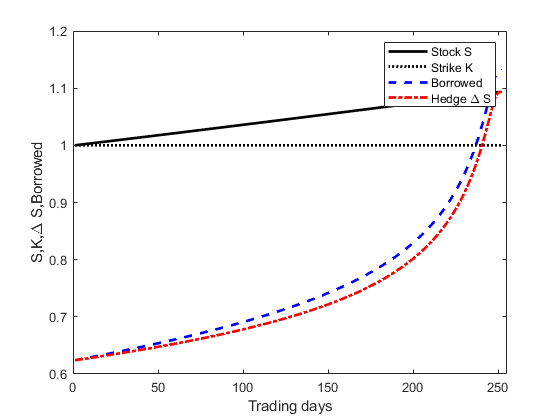

nn=1:N;

plot(nn,S,'k-',nn,KK,'k:',nn,borrow,'b--',nn,hedge,'r-.','LineWidth',2); 
xlim([0,255]); 
xlabel('Trading days')
ylabel('S,K,\Delta S,Borrowed')
legend('Stock S','Strike K','Borrowed','Hedge \Delta S')

The values set by the sliders at the start lead to the upper plot in Figure 5.3, while in the lower plot `K` was increased to 1.2, such that the hedge can be reduced to zero as it cecomes more and more obvious at we do not have to hand over a stock at maturity.

## Appendix

The function `black_scholes_call() `receives the initial stock value `S0`, the strike price `K`, the time until maturity `dt`, the risk-free rate `rf`, and the volatility `sig `as input and returns the value of a call option `c`, its `delta` and the two other Greeks `gamma` and `theta`, which are discussed in Section 6.1.

function [c,delta,gamma,theta]=black_scholes_call(S0,K,dt,rf,sig)
N=@(z)0.5*erfc(-z/sqrt(2));
d1=(log(S0./K)+(rf+0.5.*sig.^2).*dt)./(sig.*sqrt(dt));
d2=(log(S0./K)+(rf-0.5.*sig.^2).*dt)./(sig.*sqrt(dt));
c=S0.*N(d1)-K.*exp(-rf.*dt).*N(d2);
delta=N(d1);
gamma=exp(-0.5*d1.^2)./(S0.*sqrt(2*pi*sig.^2.*dt));
theta=-0.5*(sig.^2).*(S0.^2).*gamma-rf.*K.*exp(-rf.*dt).*N(d2);
end